FRA+EDFA/EDFA+FRA

raman Pump= 350mw

980nm Pump 30-100mw

Gain和NF

clc;
clear;

EDFA

% EDFA data
Pin_edfa = [-34.44];
Pase_edfa = [-54.3630  -46.1650  -41.5350  -38.7210  -36.8420  -35.4740  -34.4160  -33.5670];
Pout_edfa = [-24.241 -16.205 -11.724 -9.087 -7.360 -6.067 -5.170 -4.371];

Pin_edfa=10.^(Pin_edfa./10)*1e-3;
Pase_edfa=10.^(Pase_edfa./10)*1e-3;
Pout_edfa=10.^(Pout_edfa./10)*1e-3;

c=3e8;
h=6.62606896e-34;
wavelength=1550.912e-9;
v=c./wavelength;
Be=0.02e-9.*c./(wavelength^2);

% EDFA
Gain_edfa = (Pout_edfa - Pase_edfa) ./ Pin_edfa;
GAIN_edfa = 10.*log10(Gain_edfa)

GAIN_edfa =    10.1948   18.2306   22.7115   25.3483   27.0751   28.3680   29.2648   30.0638


NF_edfa_mw = ((2*Pase_edfa) ./ (Gain_edfa.*h*v*Be) + (1./Gain_edfa));
NF_edfa = 10.*log10((2*Pase_edfa) ./ (Gain_edfa.*h*v*Be) + (1./Gain_edfa))

NF_edfa =     3.5904    3.5956    3.7260    3.8985    4.0489    4.1231    4.2837    4.3334


NF_edfa = [    3.5904    3.5956    3.7260    3.8985    4.0489    4.1231    4.5837    5.3334];

FRA+EDFA(a->b)

%raman data
Pin_raman= -34.51;       % Gnet
Pase_raman = [-50.61];     % power of ASE
Pout_on = [-22.73];
Pout_off = -43.32;

% EDFA data
Pin_edfa = [-22.73];
Pase_edfa = [-34.38 -29.80 -27.25 -25.51 -24.24 -23.25 -22.42 -21.74];
Pout_edfa = [-14.4 -9.97 -7.48 -5.82 -4.5 -3.6 -2.7 -2.00];


% represent in W
Pin_raman=10.^(Pin_raman./10)*1e-3;
Pase_raman=10.^(Pase_raman./10)*1e-3;
Pout_on=10.^(Pout_on./10)*1e-3;
Pout_off=10.^(Pout_off./10)*1e-3;

Pin_edfa=10.^(Pin_edfa./10)*1e-3;
Pase_edfa=10.^(Pase_edfa./10)*1e-3;
Pout_edfa=10.^(Pout_edfa./10)*1e-3;

c=3e8;
h=6.62606896e-34;
wavelength=1552.912e-9;
v=c./wavelength;
Be=0.02e-9.*c./(wavelength^2);

% Raman
Gain_raman = (Pout_on - Pase_raman) ./ Pin_raman;
GAIN_raman = 10.*log10(Gain_raman)

GAIN_raman = 11.7729

Geq_raman = (Pout_on)./(Pout_off);
GEQ_raman = 10.*log10(Geq_raman)

GEQ_raman = 20.5900

NF_raman = 10.*log10( (Pase_raman) ./ (Gain_raman.*h*v*Be) + (1./Gain_raman));
NFeq_raman_mw = ((Pase_raman) ./ (Geq_raman.*h*v*Be) + (1./Geq_raman));
NFeq_raman = 10.*log10((Pase_raman) ./ (Geq_raman.*h*v*Be) + (1./Geq_raman))

NFeq_raman = -6.0746

% EDFA
Gain_edfa_first = (Pout_edfa - Pase_edfa) ./ Pin_edfa;
GAIN_edfa_first = 10.*log10(Gain_edfa_first)

GAIN_edfa_first =     8.2861   12.7146   15.2040   16.8631   18.1836   19.0827   19.9834   20.6836


NF_edfa_mw = ((2*Pase_edfa) ./ (Gain_edfa_first.*h*v*Be) + (1./Gain_edfa_first));
NF_edfa_first = 10.*log10((2*Pase_edfa) ./ (Gain_edfa_first.*h*v*Be) + (1./Gain_edfa_first))

NF_edfa_first =    25.3152   25.4655   25.5258   25.6066   25.5560   25.6469   25.5761   25.5559


% total
GAIN_total1 = GAIN_raman + GAIN_edfa_first

GAIN_total1 =    20.0591   24.4875   26.9769   28.6360   29.9566   30.8556   31.7563   32.4566


GAIN_total = GEQ_raman + GAIN_edfa_first

GAIN_total =    28.8761   33.3046   35.7940   37.4531   38.7736   39.6727   40.5734   41.2736


NF_total = NFeq_raman + NF_edfa_first ./ GAIN_raman 

NF_total =    -3.9243   -3.9115   -3.9064   -3.8995   -3.9038   -3.8961   -3.9021   -3.9038


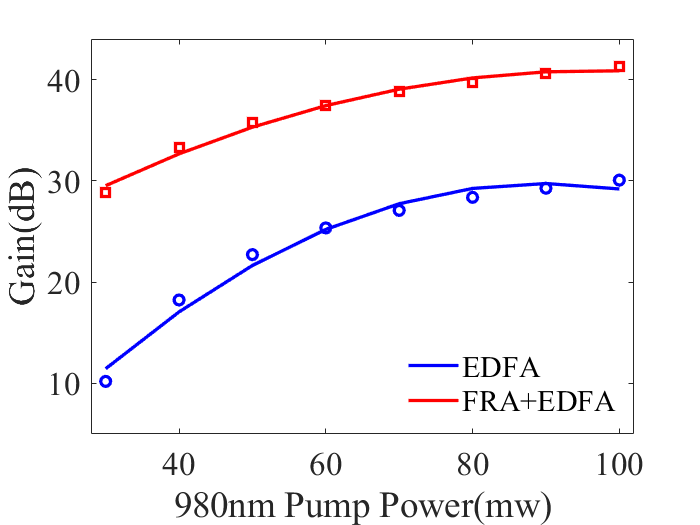

figure('Name','Gain - EDFA VS FRA+EDFA','NumberTitle','off');
box on;
hold on;
Pump = 30:10:100;

p1=polyfit(Pump,GAIN_edfa,2);
y1=polyval(p1,Pump);
c11 = plot(Pump,y1,'b-','LineWidth',2);
p2=polyfit(Pump,GAIN_total,2);
y2=polyval(p2,Pump);
c12 = plot(Pump,y2,'r-','LineWidth',2);

plot(Pump,GAIN_edfa,'bo','LineWidth',2);
plot(Pump,GAIN_total,'rs','LineWidth',2);
hold off;

axis([28 102 5 44]);
xlabel('980nm Pump Power(mw)','FontSize',20,'Fontname', 'Times New Roman');
ylabel('Gain(dB)','FontSize',20,'Fontname', 'Times New Roman');
set(gca,'FontSize',20,'Fontname', 'Times New Roman');
% set(gca,'xtick',[-45 -40 -35 -30 -25 -20]);
legend({'EDFA','FRA+EDFA'},'Location','southeast','NumColumns',1)
legend('boxoff')

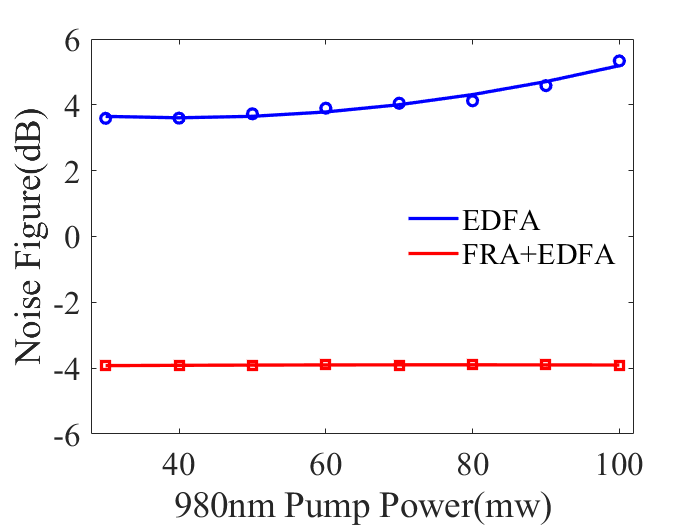

figure('Name','NF - EDFA VS FRA+EDFA','NumberTitle','off');
box on;
hold on;
Pump = 30:10:100;

p1=polyfit(Pump,NF_edfa,2);
y1=polyval(p1,Pump);
c11 = plot(Pump,y1,'b-','LineWidth',2);
p2=polyfit(Pump,NF_total,2);
y2=polyval(p2,Pump);
c12 = plot(Pump,y2,'r-','LineWidth',2); 

plot(Pump,NF_edfa,'bo','LineWidth',2);
plot(Pump,NF_total,'rs','LineWidth',2);
hold off;

axis([28 102 -6 6]);
xlabel('980nm Pump Power(mw)','FontSize',20,'Fontname', 'Times New Roman');
ylabel('Noise Figure(dB)','FontSize',20,'Fontname', 'Times New Roman');
set(gca,'FontSize',20,'Fontname', 'Times New Roman');
% set(gca,'xtick',[-45 -40 -35 -30 -25 -20]);
legend({'EDFA','FRA+EDFA'},'Location','east','NumColumns',1)
legend('boxoff')

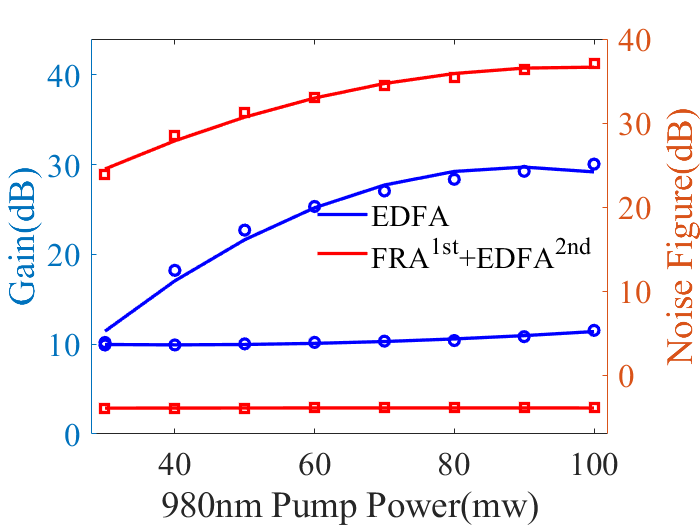

figure('Name','Gain - EDFA VS FRA+EDFA','NumberTitle','off');
box on;
hold on;
Pump = 30:10:100;

yyaxis left;
p1=polyfit(Pump,GAIN_edfa,2);
y1=polyval(p1,Pump);
plot(Pump,y1,'b-','LineWidth',2);
p2=polyfit(Pump,GAIN_total,2);
y2=polyval(p2,Pump);
plot(Pump,y2,'r-','LineWidth',2);

yyaxis right;
p1=polyfit(Pump,NF_edfa,2);
y1=polyval(p1,Pump);
c11 = plot(Pump,y1,'b-','LineWidth',2);
p2=polyfit(Pump,NF_total,2);
y2=polyval(p2,Pump);
c12 = plot(Pump,y2,'r-','LineWidth',2); 

yyaxis left;
plot(Pump,GAIN_edfa,'bo','LineWidth',2);
plot(Pump,GAIN_total,'rs','LineWidth',2);

yyaxis right;
plot(Pump,NF_edfa,'bo','LineWidth',2);
plot(Pump,NF_total,'rs','LineWidth',2);
hold off;

yyaxis left;
axis([28 102 0 44]);
xlabel('980nm Pump Power(mw)','FontSize',20,'Fontname', 'Times New Roman');
ylabel('Gain(dB)','FontSize',20,'Fontname', 'Times New Roman');
yyaxis right;
axis([28 102 -7 40]);
ylabel('Noise Figure(dB)','FontSize',20,'Fontname', 'Times New Roman');
set(gca,'FontSize',20,'Fontname', 'Times New Roman');
% set(gca,'xtick',[-45 -40 -35 -30 -25 -20]);
legend({'EDFA','FRA^1^s^t+EDFA^2^n^d'},'Location','east','NumColumns',1)
legend('boxoff')